# Result Analyze

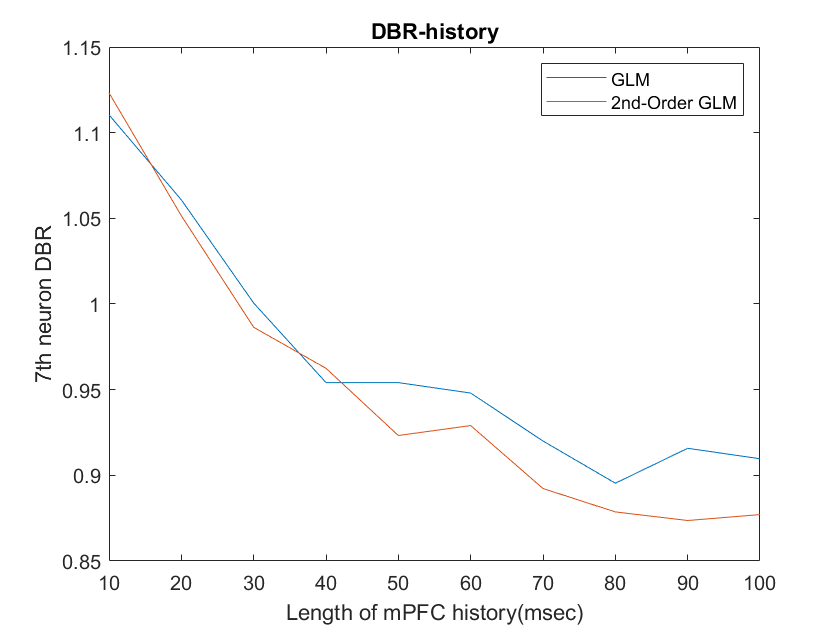

close all;clear;clc;
load data\data_rat010_0615_spike_train_selected.mat
load results\GLM_explore_H.mat
load results\GLM_sec_explore_H.mat

% get DBRs from differnt model result
GLM_sec_DBR = zeros(1,10);
GLM_DBR = zeros(1,10);
for i=1:10
  GLM_DBR(i)     = GLM_explore_H(i).DBR;
  GLM_sec_DBR(i) = GLM_sec_explore_H(i).DBR;
end
% plot DBR-history result
figure(1)
plot(10:10:100, GLM_DBR)
hold on
plot(10:10:100, GLM_sec_DBR)
hold off
legend("GLM", "2nd-Order GLM")
xlabel("Length of mPFC history(msec)")
xlim([10 100])
ylabel("7th neuron DBR")
title("DBR-history")

Take history = 90msec, kernel size = 0.6s

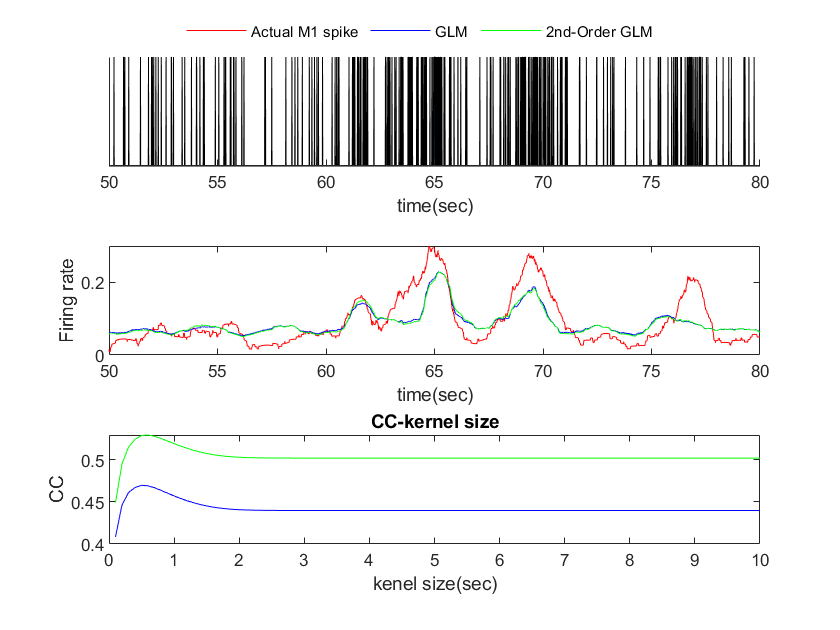

% get GLM params & test result
W     = GLM_explore_H(9).W;
H     = GLM_explore_H(9).H;
M1Idx = GLM_explore_H(9).M1Idx;
[~,~,~,~,~,testX,~,~,testY] = splitData(mPFCspike,M1spike(:,M1Idx),H);
GLMtestLambdaYpre = GLMmodel(testX, W);
GLMccList = zeros(1, 1000/10);
% smooth result
for kernelSize=10:10:1000
  smoothedLambda    = gaussianSmooth(testY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(GLMtestLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  GLMccList(kernelSize/10) = cc(2);
end

% 2nd Order GLM
W     = GLM_sec_explore_H(9).W;
H     = GLM_sec_explore_H(9).H;
M1Idx = GLM_explore_H(9).M1Idx;
[~,~,~,~,~,testX,~,~,testY] = splitDataSecOrder(mPFCspike,M1spike(:,M1Idx),H);
GLMsectestLambdaYpre = GLMmodel(testX, W);
GLM_sec_ccList = zeros(1, 1000/10);
% smooth
for kernelSize=10:10:1000
  smoothedLambda    = gaussianSmooth(testY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(GLMsectestLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  GLM_sec_ccList(kernelSize/10) = cc(2);
end

% optimal smooth kernel size result
smoothedLambda = gaussianSmooth(testY, 60);
smoothedGLMLambdaPre = gaussianSmooth(GLMtestLambdaYpre, 60);
smoothedGLMsecLambdaPre = gaussianSmooth(GLMsectestLambdaYpre, 60);

% take part of result for display
t = 50:0.01:80;
index = 5000:8000;
figure(2)
% real spike
subplot(3,1,1)
area(t, testY(index))
xlabel("time(sec)")
set(gca, 'ytick', [])
set(gca, 'box', 'off')
% smoothed results
subplot(3,1,2)
h{1} = plot(t, smoothedLambda(index), 'r');
hold on
h{2} = plot(t, smoothedGLMLambdaPre(index), 'b');
h{3} = plot(t, smoothedGLMsecLambdaPre(index), 'g');
hold off
xlabel("time(sec)")
ylabel("Firing rate")
% cc analyze
subplot(3,1,3)
plot(0.1:0.1:10, GLMccList, 'b')
hold on
plot(0.1:0.1:10, GLM_sec_ccList, 'g')
hold off
xlabel("kenel size(sec)")
xlim([0 10])
ylabel("CC")
title("CC-kernel size")
legend([h{1}; h{2}; h{3}], "Actual M1 spike", "GLM", "2nd-Order GLM", ...
    "Position",[0.5  0.95  0  0], "Box","off", "Orientation","horizontal")